### Set up workspace 

clearvars
addpath('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird_Oxygen_Toolbox')
addpath('G:\My Drive\Matlab_work\BC\Sea-Bird-Toolbox')
addpath('G:\My Drive\Matlab_work\Functions\GSW')
addpath('C:\Users\fogaren\Desktop')
cd('G:\My Drive\Matlab_work\OSU\GeneralCode')
run('GeneralSettings.m')

### Calculate oxygen sensor lag for CTD alignment 

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
% Casts 
cast02 = readSBScnv( 'KN22104002_hyst.cnv' );
cast03 = readSBScnv( 'KN22104003_hyst.cnv' );
cast04 = readSBScnv( 'KN22104004_hyst.cnv' );
cast05 = readSBScnv( 'KN22104005_hyst.cnv' );
cast06 = readSBScnv( 'KN22104006_hyst.cnv' );
cast07 = readSBScnv( 'KN22104007_hyst.cnv' );
cast08 = readSBScnv( 'KN22104008_hyst.cnv' );
cast09 = readSBScnv( 'KN22104009_hyst.cnv' );

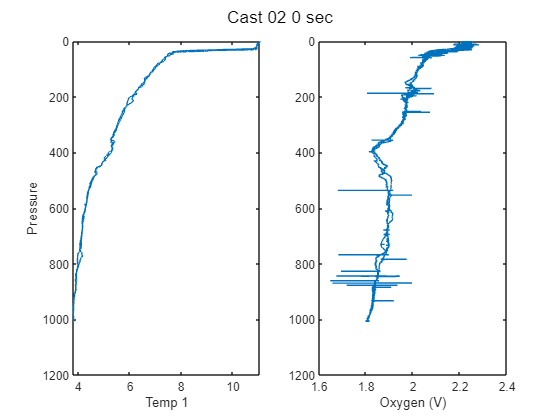

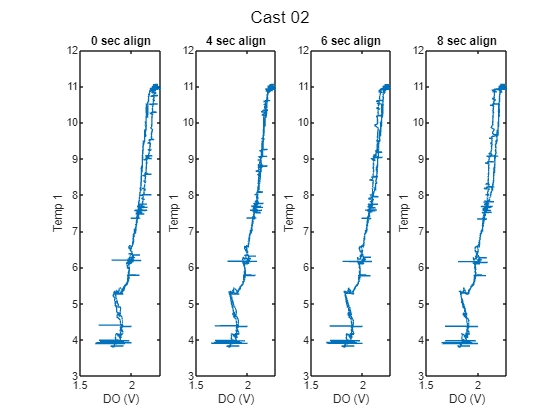

% cast = alignCTD_KF(cast,CastString,a1,a2,a3) % Function
a1 = 4; a2 = 6; a3 = 8;
cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

CTD_sen1 = 1; % Use primary or secondary CTD temp and sal
CTD_sen2 = 2; 

cast02 = align_CTD_by_sensor_KF(cast02,'Cast 02',a1,a2,a3,CTD_sen1);

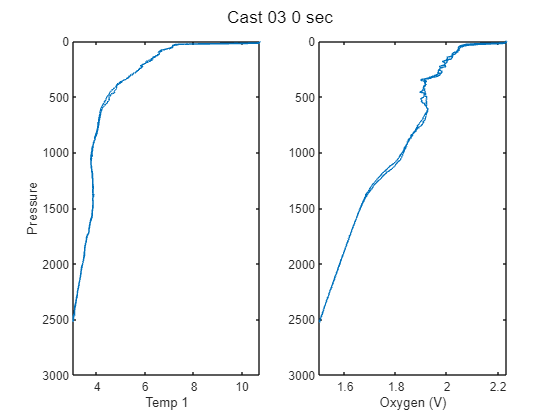

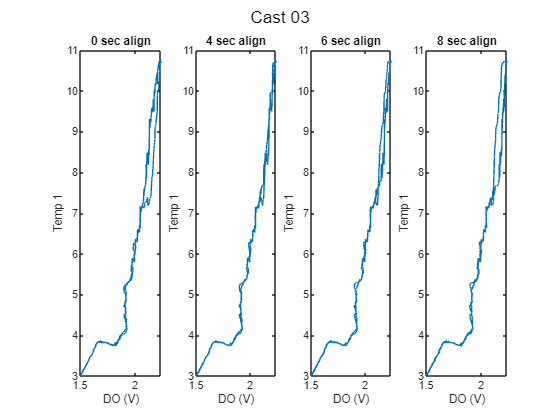

cast03 = align_CTD_by_sensor_KF(cast03,'Cast 03',a1,a2,a3,CTD_sen1);

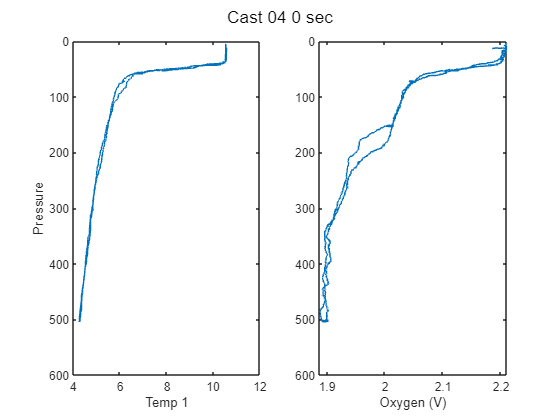

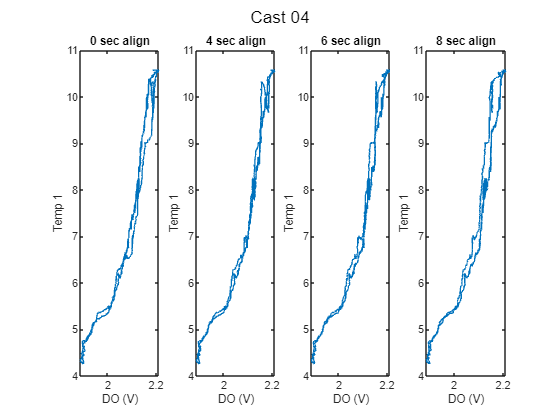

cast04 = align_CTD_by_sensor_KF(cast04,'Cast 04',a1,a2,a3,CTD_sen1);

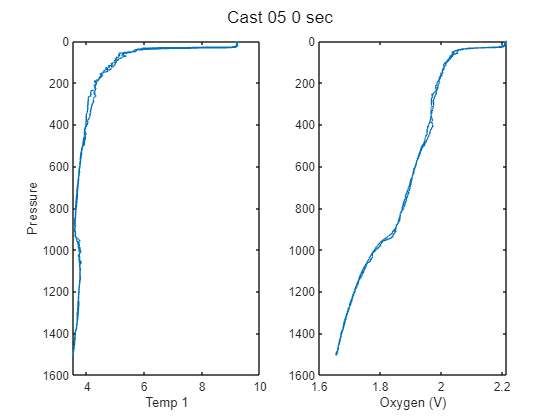

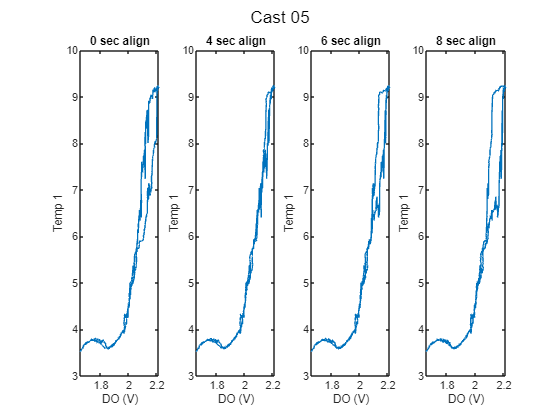

cast05 = align_CTD_by_sensor_KF(cast05,'Cast 05',a1,a2,a3,CTD_sen1);

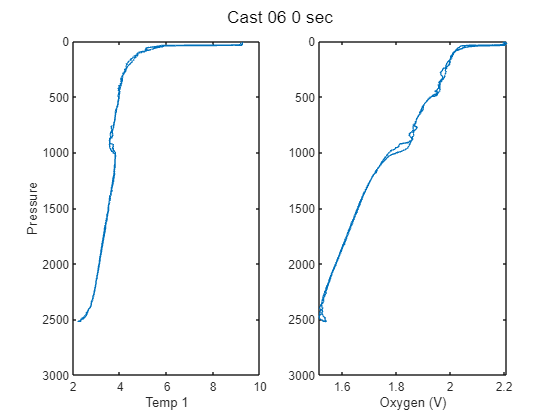

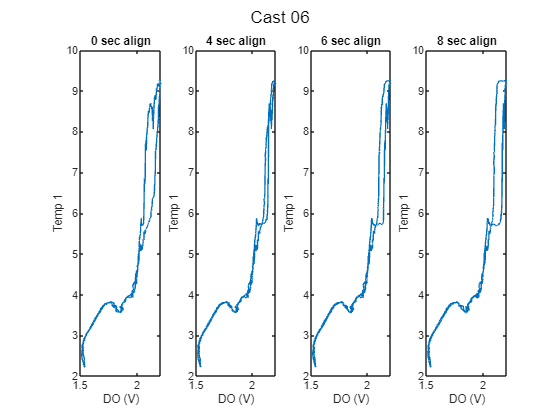

cast06 = align_CTD_by_sensor_KF(cast06,'Cast 06',a1,a2,a3,CTD_sen1);

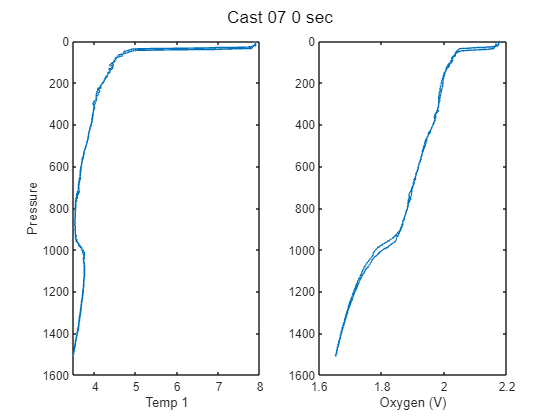

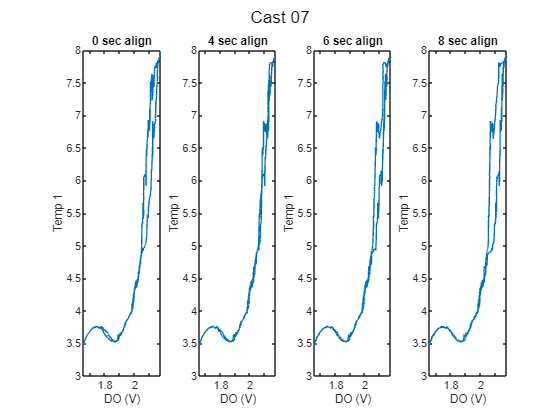

cast07 = align_CTD_by_sensor_KF(cast07,'Cast 07',a1,a2,a3,CTD_sen1);

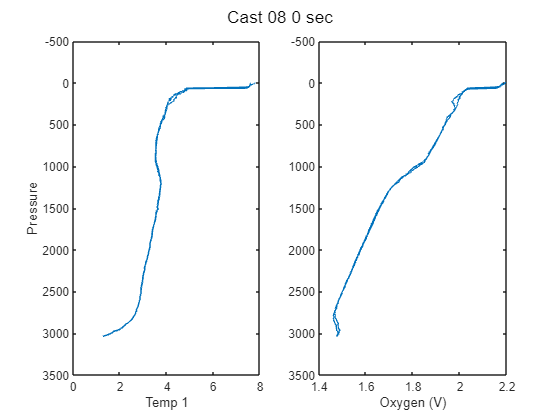

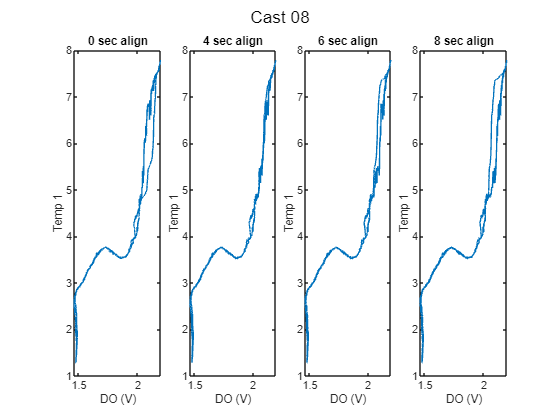

cast08 = align_CTD_by_sensor_KF(cast08,'Cast 08',a1,a2,a3,CTD_sen1);

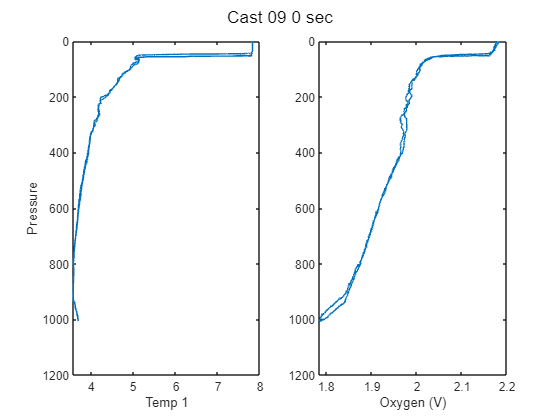

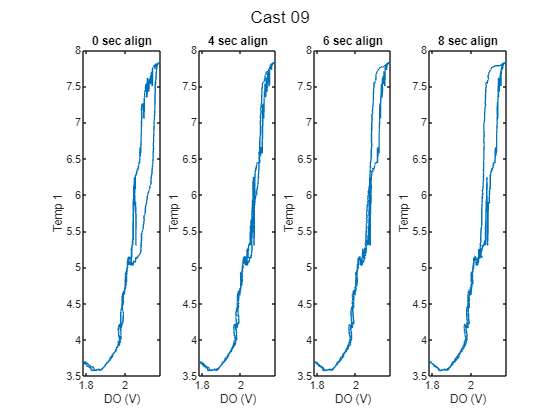

cast09 = align_CTD_by_sensor_KF(cast09,'Cast 09',a1,a2,a3,CTD_sen1);

clear cast*
% Pick align_sec
a1 = 4;
align_sec = a1; 

### Use Bottle samples to calculate new SOC (gain) and E terms for CTD data 

% Create bottle summary file with CTD oxygen calculated using calibrated
% salinity product 
addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Bottle_Files\Year1')
% addpath('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1\From_Leah')
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')

btl = readtable('Irminger_Sea-01_KN221-04_Discrete_Summary_KF.xlsx','TextType','string');
btl.Winkler_mLL = double(btl.Winkler_mLL);
btl.Discrete_Salinity_psu = double(btl.Discrete_Salinity_psu);

btlsum02 = btl(btl.Cast == 2,:);
btlsum03 = btl(btl.Cast == 3,:);
btlsum04 = btl(btl.Cast == 4,:);
btlsum05 = btl(btl.Cast == 5,:);
btlsum06 = btl(btl.Cast == 6,:);
btlsum07 = btl(btl.Cast == 7,:);
btlsum09 = btl(btl.Cast == 9,:);

btlsum02 = combine_btl_files_woutCTDcal('KN22104002.csv',btlsum02);

btlsum03 = combine_btl_files_woutCTDcal('KN22104003.csv',btlsum03);

btlsum04 = combine_btl_files_woutCTDcal('KN22104004.csv',btlsum04);

btlsum05 = combine_btl_files_woutCTDcal('KN22104005.csv',btlsum05);

btlsum06 = combine_btl_files_woutCTDcal('KN22104006.csv',btlsum06);

btlsum07 = combine_btl_files_woutCTDcal('KN22104007.csv',btlsum07);

btlsum09 = combine_btl_files_woutCTDcal('KN22104009.csv',btlsum09);


%% If get finalized finalsfrom Leah 
% btlsum02 = combine_btl_files('KN22104002.cbot_s','KN22104002.csv',btlsum02,CTD_sen1);
% btlsum03 = combine_btl_files('KN22104003.cbot_s','KN22104003.csv',btlsum03,CTD_sen1);
% btlsum04 = combine_btl_files('KN22104004.cbot_s','KN22104004.csv',btlsum04,CTD_sen1);
% btlsum05 = combine_btl_files('KN22104005.cbot_s','KN22104005.csv',btlsum05,CTD_sen1);
% btlsum06 = combine_btl_files('KN22104006.cbot_s','KN22104006.csv',btlsum06,CTD_sen1);
% btlsum07 = combine_btl_files('KN22104007.cbot_s','KN22104007.csv',btlsum07,CTD_sen1);
% btlsum09 = combine_btl_files('KN22104009.cbot_s','KN22104009.csv',btlsum09,CTD_sen1);

btlsum_yr1 = [btlsum02; btlsum03; btlsum04; btlsum05; btlsum06; btlsum07; btlsum09];
btlsum0 = btlsum_yr1; %

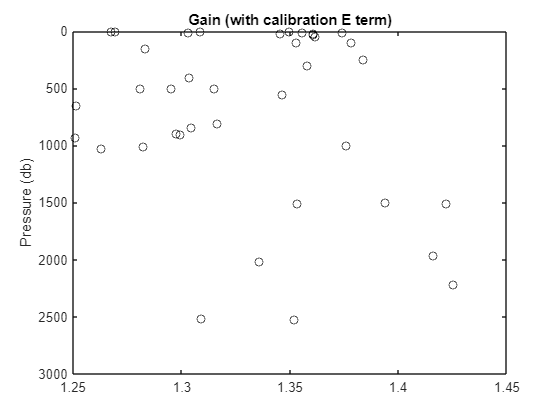

figure % Winkler/CTD Oxygen (without Leah calibrated Sal product)
plot(btlsum0.Winkler_mLL./btlsum0.CTDoxy_mLL,btlsum0.PrDM,'ok')
axis ij
ylabel('Pressure (db)')
title('Gain (with calibration E term)')

% Oxygen Sensor for cast 2 on; different one cast 1  
% Calibration standards from SBE xmlcon file 

cal.SOC = double(4.55930e-001);
cal.VOFFSET = double(-4.97100e-001);
cal.A = double(-3.66900e-003);
cal.B = double(1.91110e-004);
cal.C = double(-2.62760e-006);
cal.E = double(3.60000e-002);
cal.Tau20 = double(2.23000e+000);
cal.INSTRUMENT_TYPE = 'SBE43';
cal.SERIALNO = '1679';
cal.OCALDATE = '23-Oct-13';

H = [-0.033, 5000, 1450]; % Default 

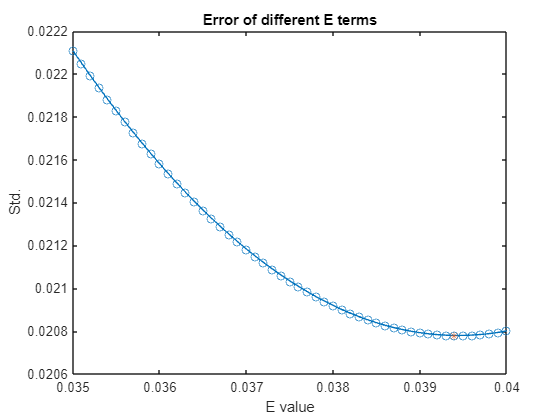

cal.E2 = 0.0394


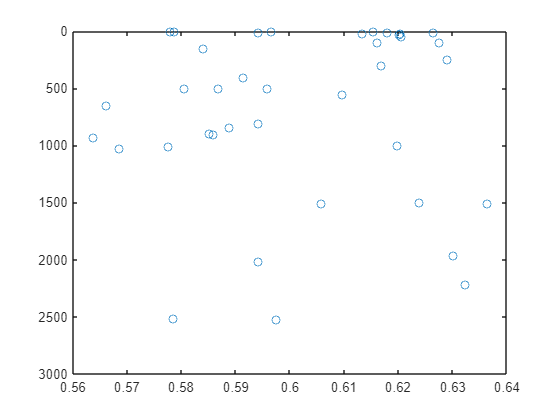

cd('G:\My Drive\Matlab_work\BC\Irminger\colab-workspace\CTD_Processing')

btlsum0.CTDoxy_mLL_cal = btlsum0.CTDoxy_mLL; % Because don't have cal product

[cal] = E2_calculation(btlsum0,cal,CTD_sen1); % Use dummy bottle summary with outlier removed

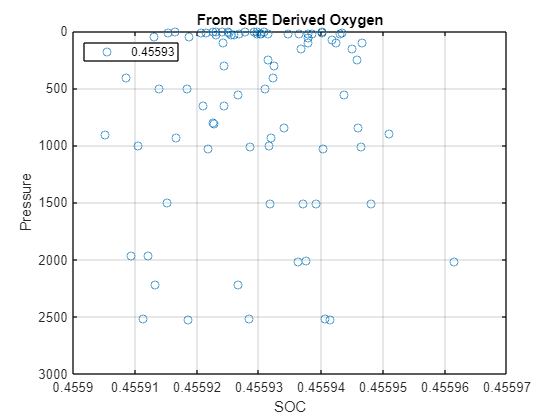

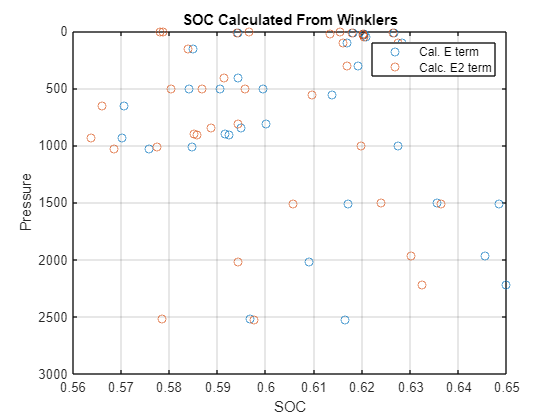

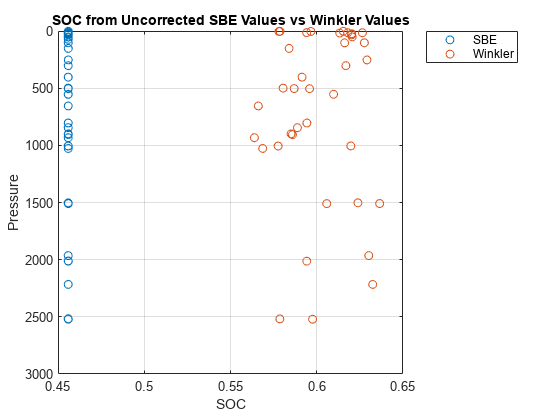

New SOC = 0.60182
EGain = 1.32+/- 0.045577



[cal] = Gain_E2_Calculation(btlsum0,cal,CTD_sen1); % Use dummy bottle summary with any outliers removed

% Read in processed casts
% Processed with 4 sec DO alignment and SBE cal hysteresis, SOC, and E term
% 
cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
cast02u = readSBScnv( 'uKN22104002.cnv' );
cast03u = readSBScnv( 'uKN22104003.cnv' );
cast04u = readSBScnv( 'uKN22104004.cnv' );
cast05u = readSBScnv( 'uKN22104005.cnv' );
cast06u = readSBScnv( 'uKN22104006.cnv' );
cast07u = readSBScnv( 'uKN22104007.cnv' );
cast08u = readSBScnv( 'uKN22104008.cnv' );
cast09u = readSBScnv( 'uKN22104009.cnv' );

cast02d = readSBScnv( 'dKN22104002.cnv' );
cast03d = readSBScnv( 'dKN22104003.cnv' );
cast04d = readSBScnv( 'dKN22104004.cnv' );
cast05d = readSBScnv( 'dKN22104005.cnv' );
cast06d = readSBScnv( 'dKN22104006.cnv' );
cast07d = readSBScnv( 'dKN22104007.cnv' );
cast08d = readSBScnv( 'dKN22104008.cnv' );
cast09d = readSBScnv( 'dKN22104009.cnv' );

% % Format to table without Leah's product 
% [cast02u, cast02u0] = combine_CTD_files_woutCTDcal(cast02u); [cast02d, cast02d0] = combine_CTD_files_woutCTDcal(cast02d);  
% [cast03u, cast03u0] = combine_CTD_files_woutCTDcal(cast03u); [cast03d, cast03d0] = combine_CTD_files_woutCTDcal(cast03d);  
% [cast04u, cast04u0] = combine_CTD_files_woutCTDcal(cast04u); [cast04d, cast04d0] = combine_CTD_files_woutCTDcal(cast04d);  
% [cast05u, cast05u0] = combine_CTD_files_woutCTDcal(cast05u); [cast05d, cast05d0] = combine_CTD_files_woutCTDcal(cast05d);  
% [cast06u, cast06u0] = combine_CTD_files_woutCTDcal(cast06u); [cast06d, cast06d0] = combine_CTD_files_woutCTDcal(cast06d);  
% [cast07u, cast07u0] = combine_CTD_files_woutCTDcal(cast07u); [cast07d, cast07d0] = combine_CTD_files_woutCTDcal(cast07d);  
% [cast08u, cast08u0] = combine_CTD_files_woutCTDcal(cast08u); [cast08d, cast08d0] = combine_CTD_files_woutCTDcal(cast08d);  
% [cast09u, cast09u0] = combine_CTD_files_woutCTDcal(cast09u); [cast09d, cast09d0] = combine_CTD_files_woutCTDcal(cast09d);  

% Format to table without Leah's product 
[cast02u, ~] = combine_CTD_files_woutCTDcal(cast02u); [cast02d, ~] = combine_CTD_files_woutCTDcal(cast02d);  
[cast03u, ~] = combine_CTD_files_woutCTDcal(cast03u); [cast03d, ~] = combine_CTD_files_woutCTDcal(cast03d);  
[cast04u, ~] = combine_CTD_files_woutCTDcal(cast04u); [cast04d, ~] = combine_CTD_files_woutCTDcal(cast04d);  
[cast05u, ~] = combine_CTD_files_woutCTDcal(cast05u); [cast05d, ~] = combine_CTD_files_woutCTDcal(cast05d);  
[cast06u, ~] = combine_CTD_files_woutCTDcal(cast06u); [cast06d, ~] = combine_CTD_files_woutCTDcal(cast06d);  
[cast07u, ~] = combine_CTD_files_woutCTDcal(cast07u); [cast07d, ~] = combine_CTD_files_woutCTDcal(cast07d);  
[cast08u, ~] = combine_CTD_files_woutCTDcal(cast08u); [cast08d, ~] = combine_CTD_files_woutCTDcal(cast08d);  
[cast09u, ~] = combine_CTD_files_woutCTDcal(cast09u); [cast09d, ~] = combine_CTD_files_woutCTDcal(cast09d);  


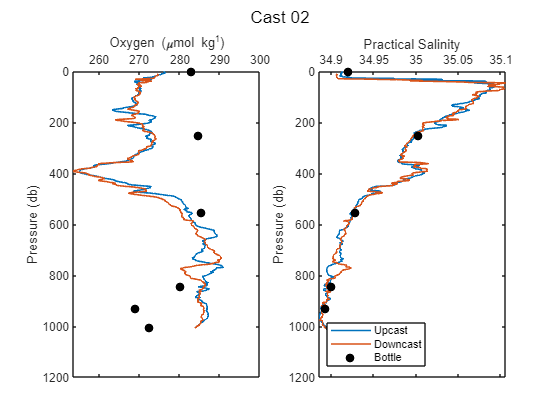

% Using function written for missing final Sal product 
sal_plots = 1; leah_plot = 0; 
% [castu, castd, btlsum] = Process_Cast_Gain_E2_woutCTDcal(castu,castd,cal,btlsum,sal_plots,leah_plots,CTD_sen,CastString)

[cast02u, cast02d, btlsum02] = Process_Cast_Gain_E2_woutCTDcal(cast02u,cast02d,cal,btlsum02,sal_plots,leah_plot,CTD_sen1,'Cast 02');

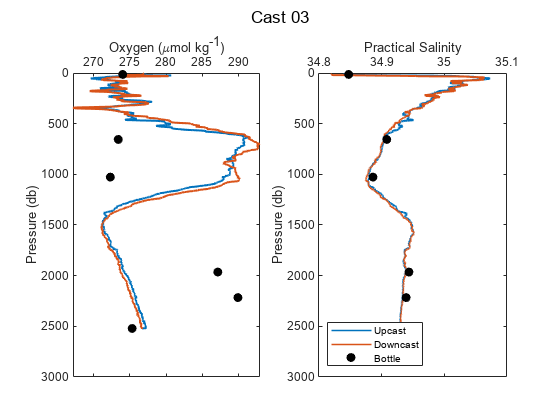

[cast03u, cast03d, btlsum03] = Process_Cast_Gain_E2_woutCTDcal(cast03u,cast03d,cal,btlsum03,sal_plots,leah_plot,CTD_sen1,'Cast 03');

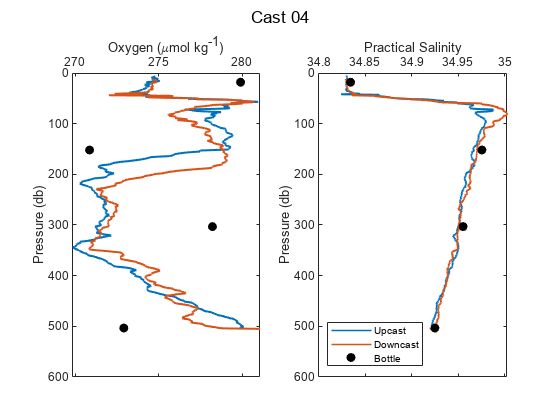

[cast04u, cast04d, btlsum04] = Process_Cast_Gain_E2_woutCTDcal(cast04u,cast04d,cal,btlsum04,sal_plots,leah_plot,CTD_sen1,'Cast 04');

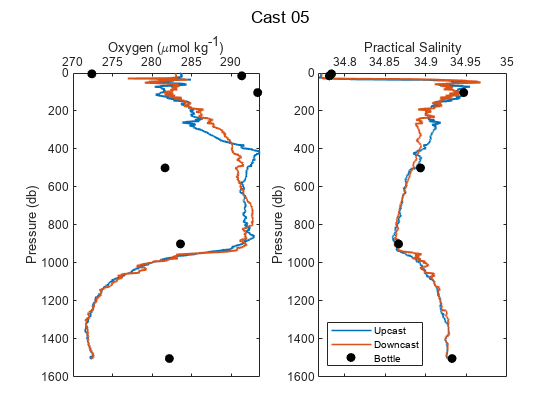

[cast05u, cast05d, btlsum05] = Process_Cast_Gain_E2_woutCTDcal(cast05u,cast05d,cal,btlsum05,sal_plots,leah_plot,CTD_sen1,'Cast 05');

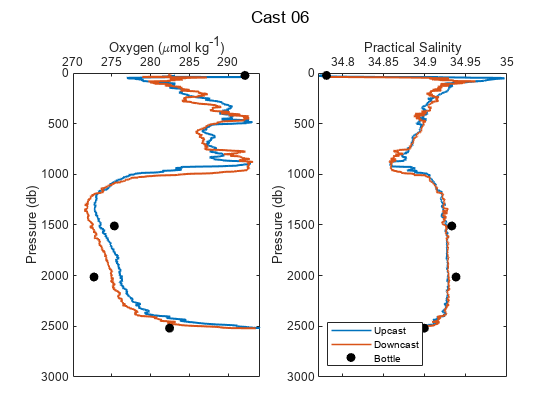

[cast06u, cast06d, btlsum06] = Process_Cast_Gain_E2_woutCTDcal(cast06u,cast06d,cal,btlsum06,sal_plots,leah_plot,CTD_sen1,'Cast 06');

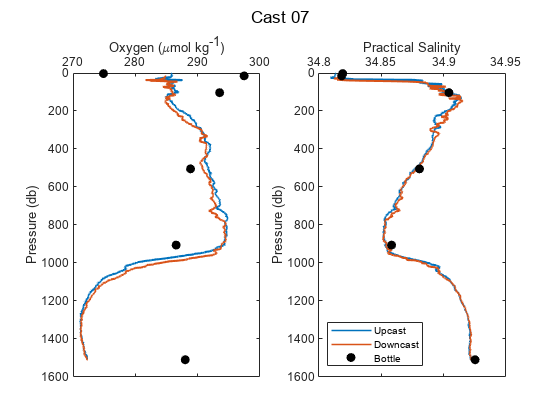

[cast07u, cast07d, btlsum07] = Process_Cast_Gain_E2_woutCTDcal(cast07u,cast07d,cal,btlsum07,sal_plots,leah_plot,CTD_sen1,'Cast 07');

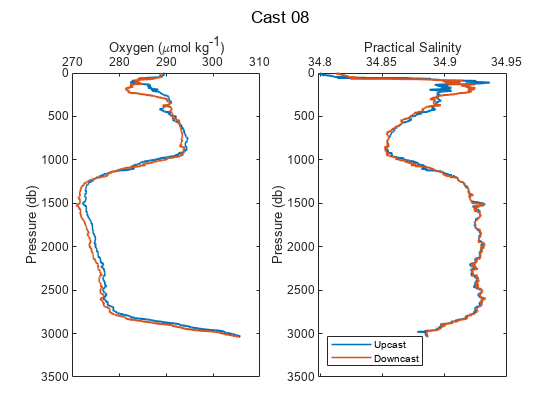

[cast08u, cast08d, btlsum08] = Process_Cast_Gain_E2_woutCTDcal(cast08u,cast08d,cal,0,sal_plots,leah_plot,CTD_sen1,'Cast 08');

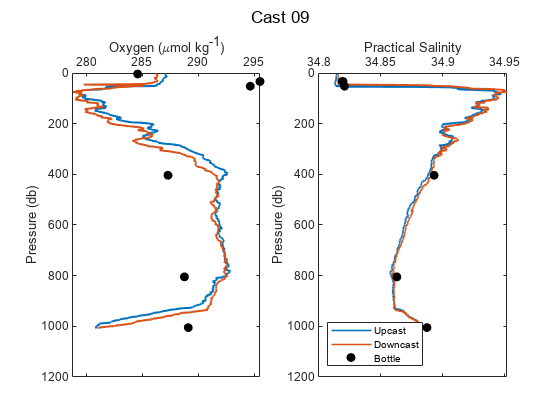

[cast09u, cast09d, btlsum09] = Process_Cast_Gain_E2_woutCTDcal(cast09u,cast09d,cal,btlsum09,sal_plots,leah_plot,CTD_sen1,'Cast 09');

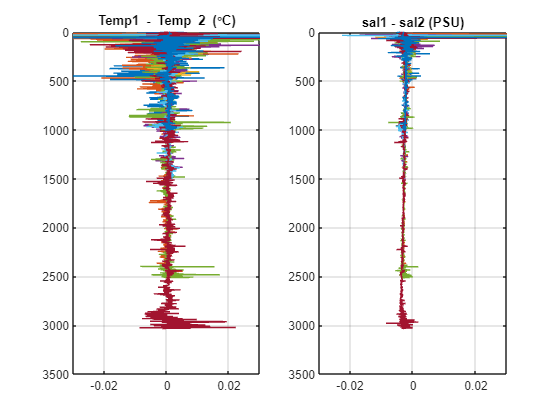

figure
subplot(1,2,1)
plot(cast02u.temp1-cast02u.temp2,cast02u.prs)
hold on
plot(cast03u.temp1-cast03u.temp2,cast03u.prs)
plot(cast04u.temp1-cast04u.temp2,cast04u.prs)
plot(cast05u.temp1-cast05u.temp2,cast05u.prs)
plot(cast06u.temp1-cast06u.temp2,cast06u.prs)
plot(cast07u.temp1-cast07u.temp2,cast07u.prs)
plot(cast08u.temp1-cast08u.temp2,cast08u.prs)
plot(cast09u.temp1-cast09u.temp2,cast09u.prs)
axis ij
grid on
xlim([-0.03 0.03])
title('Temp1 - Temp 2 (\circC)')
% legend('Cast2','Cast3','Cast4','Cast5','Cast6','Cast7','Cast8','Cast9',...
%     'Location','southoutside','Orientation',"horizontal")

subplot(1,2,2)
plot(cast02u.sal1-cast02u.sal2,cast02u.prs)
hold on
plot(cast03u.sal1-cast03u.sal2,cast03u.prs)
plot(cast04u.sal1-cast04u.sal2,cast04u.prs)
plot(cast05u.sal1-cast05u.sal2,cast05u.prs)
plot(cast06u.sal1-cast06u.sal2,cast06u.prs)
plot(cast07u.sal1-cast07u.sal2,cast07u.prs)
plot(cast08u.sal1-cast08u.sal2,cast08u.prs)
plot(cast09u.sal1-cast09u.sal2,cast09u.prs)
axis ij
grid on
xlim([-0.03 0.03])
title('sal1 - sal2 (PSU)')

btlsum_yr1 = [btlsum02; btlsum03; btlsum04; btlsum05; btlsum06; btlsum07; btlsum09];
btlsum_yr1_OOI = [btlsum05; btlsum06; btlsum07; btlsum09];

disp(['DO align (s) = ' num2str(align_sec)])

DO align (s) = 4


disp(['Cal. E term = ' num2str(cal.E)])

Cal. E term = 0.036


disp(['Adjust. E term (E2) = ' num2str(cal.E2)])

Adjust. E term (E2) = 0.0394


disp(['Cal SOC = ' num2str(cal.SOC)])

Cal SOC = 0.45593


disp(['New SOC = ' num2str(cal.SOCnew) ])

New SOC = 0.60182


disp(['E2Gain = ' num2str(cal.E2gain) '+/- ' num2str(cal.E2gainSTD)])

E2Gain = 1.32+/- 0.045577


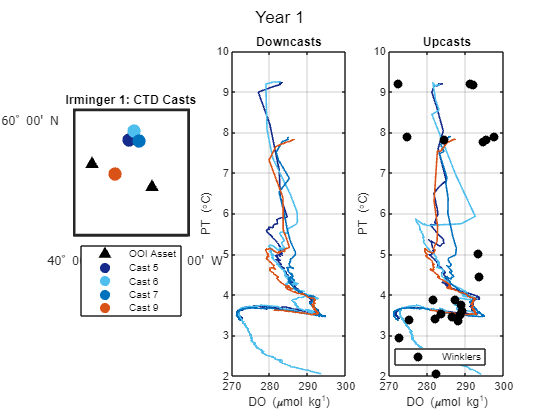

run('Year1_PT_DO_plots.m')

cd('G:\Shared drives\NSF_Irminger\OOI Cruises CTD Casts\CTD_Data\Alfresco\Year1')
clear btlsum0 btl
dt_Processed = datetime;
save Year1_Processed_KF cast* btl* cal* dt_Processed 



